g=9.81;         % m/s^2
m=0.217;        % kg
l=0.240;        % m
tau=1.030;      % s
zeta=0.0185476; % 
omega_n = (2*pi())/(tau*sqrt(1-zeta^2));

format long; I_xx_kgsm = ((m*g*l*tau^2*(1-(zeta^2)))/(4*pi()^2))-m*l^2    % kg.m^2

I_xx_kgsm =    0.001225576052298


I_tot = I_xx_kgsm + m*l^2

I_tot =    0.013724776052298


format bank; I_xx_gsmm = I_xx_kgsm*10^9

I_xx_gsmm =     1225576.05



format long; c = 2*(I_xx_kgsm+m*l^2)*zeta*(2*pi())/(tau*sqrt(1-zeta^2))

c =    0.003106278149984



params_init = [I_tot; c; 0]%; m; g; l];

params_init =    0.013724776052298
   0.003106278149984
                   0



Ts = 0.01;

theta0 = data(1);
dtheta0 = (data(2)-data(1))/Ts;
sysnl = idnlgrey('nl_greybox_ss', [1 0 2], params_init, [theta0; dtheta0], 0);

sysnl.Parameters(1).Name = 'I';
sysnl.Parameters(1).Minimum = 0;          % Limit I to positive
sysnl.Parameters(2).Name = 'c1';
sysnl.Parameters(2).Fixed = true;          % Limit c1 to positive
sysnl.Parameters(3).Name = 'c2';
sysnl.Parameters(3).Fixed = true;         % Limit c2 to positive
% sysnl.Parameters(4).Name = 'm';
% sysnl.Parameters(4).Fixed = true;         % fix m
% sysnl.Parameters(5).Name = 'g';
% sysnl.Parameters(5).Fixed = true;         % fix g
% sysnl.Parameters(6).Name = 'l';
% sysnl.Parameters(6).Fixed = true;         % fix l
sysnl.InitialStates(1).Fixed = true;     % estimate theta(0)
sysnl.InitialStates(2).Fixed = true;     % estimate dtheta(0)

sysnl

sysnl =

Discrete-time nonlinear grey-box model defined by 'nl_greybox_ss' (MATLAB file):

   x(t+Ts) = F(t, u(t), x(t), p1, ..., p3)
      y(t) = H(t, x(t), p1, ..., p3) + e(t)

 with 0 input(s), 2 state(s), 1 output(s), and 1 free parameter(s) (out of 3).

Sample time: 0.01 seconds

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties



% simout = initial(sysnl, [theta0;dtheta0], 10);
% plot(Ts*(0:length(simout)-1), simout)

test_data = iddata(data,[],Ts);

sysEst = nlgreyest(test_data,sysnl)

sysEst =

Discrete-time nonlinear grey-box model defined by 'nl_greybox_ss' (MATLAB file):

   x(t+Ts) = F(t, u(t), x(t), p1, ..., p3)
      y(t) = H(t, x(t), p1, ..., p3) + e(t)

 with 0 input(s), 2 state(s), 1 output(s), and 1 free parameter(s) (out of 3).

Sample time: 0.01 seconds

Status:                                                                                      
Estimated using Solver: FixedStepDiscrete; Search: lsqnonlin on time domain data "test_data".
Fit to estimation data: -1.183e+04%                                                          
FPE: 678.5, MSE: 676.6                                                                       

Model Properties


sysEst.Parameters

ans = 3×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


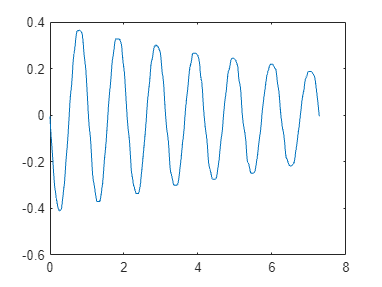


plot(Ts*(0:(729-1)),data)

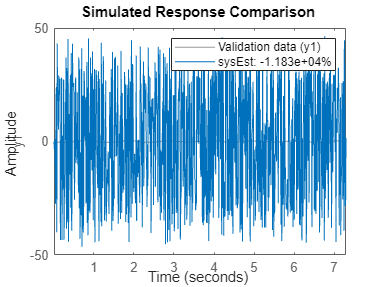

compare(test_data, sysEst)